## Reading image

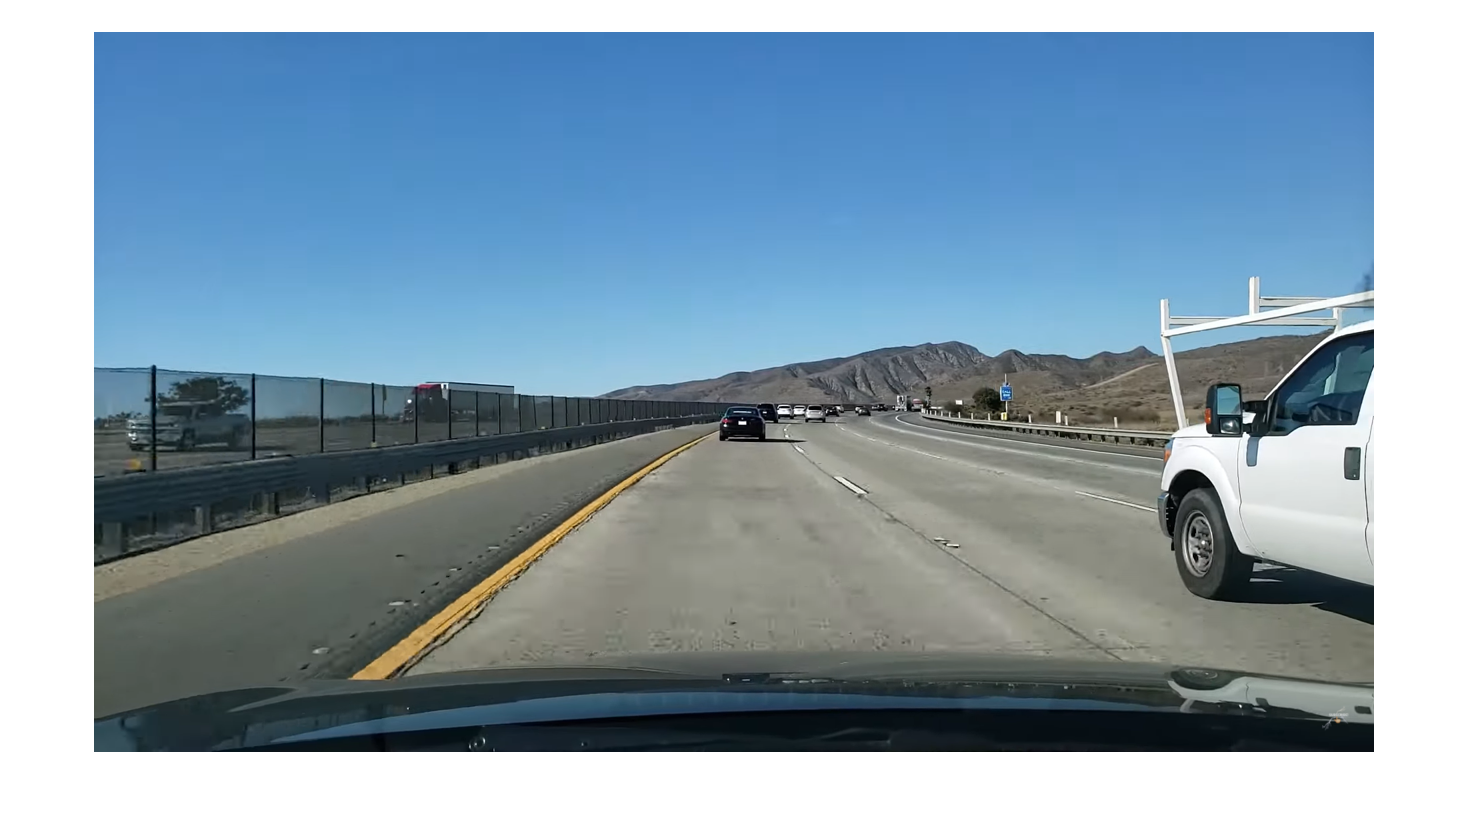

img = imread("test_images\test10.png");
hd_resolution = [720 1280];
img = imresize(img, hd_resolution);
imshow(img)

## Lane detection

leftLineOriginal = getLeftLineOnOriginalImage(img);
rightLineOriginal = getRightLineOnOriginalImage(img);
leftLineLong = spreadLineToLimits(leftLineOriginal, 450, 640);
rightLineLong = spreadLineToLimits(rightLineOriginal, 450, 625);

## Distance estimator

[model, C, S] = loadSavedDistanceEstimator();
[dist, bounds] = estimateDistance(img, model, C, S);
if dist >= 0
    img = insertObjectAnnotation(img, 'rectangle', bounds, strcat(string(dist), " m"),...
            'LineWidth', 3, 'FontSize', 18);
end

## Output image

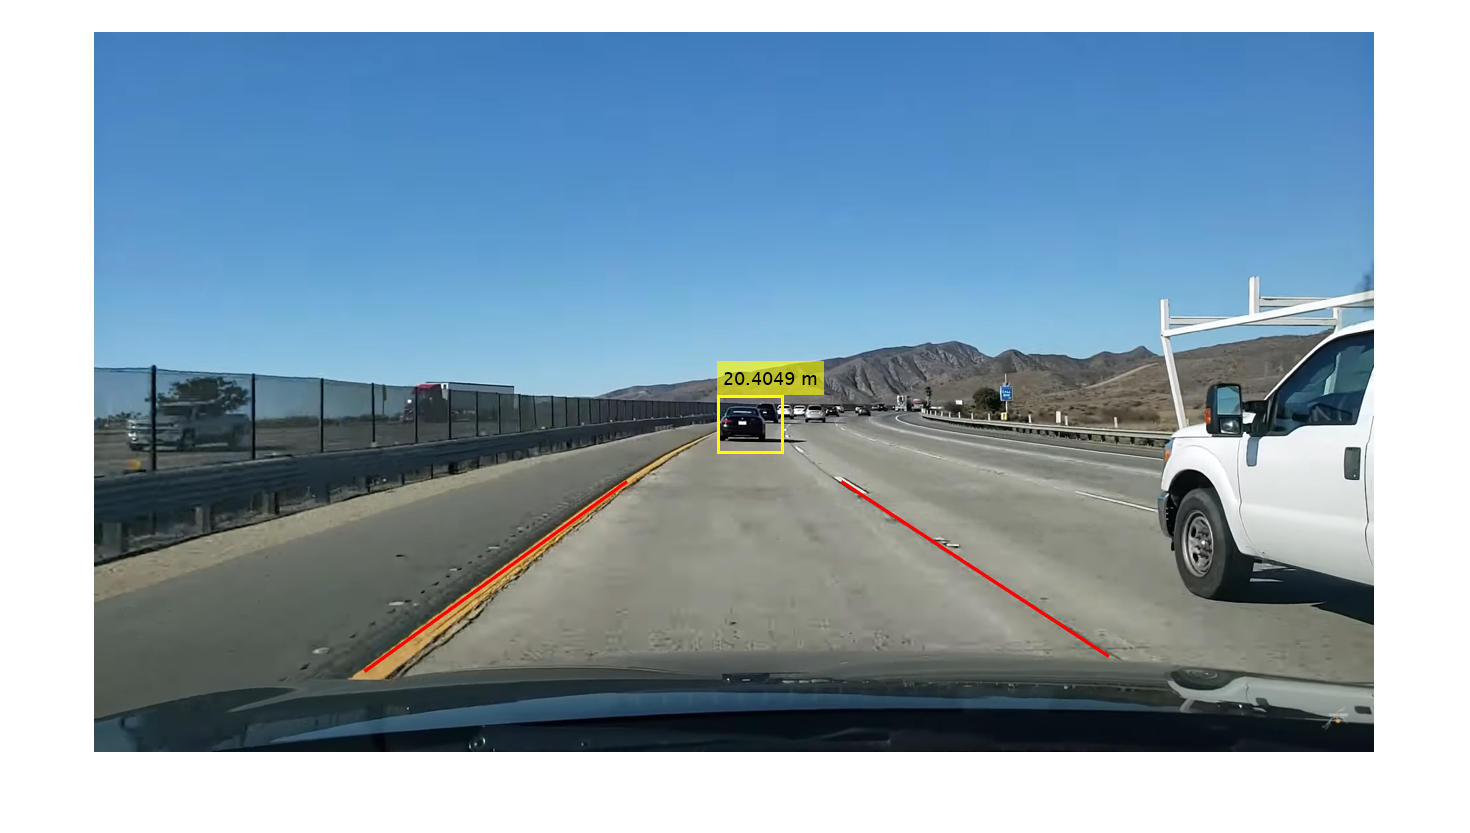

imshow(img)
hold on; plotLine(leftLineLong); hold off;
hold on; plotLine(rightLineLong); hold off;